# R11521212 鄭傳嶧 HW10

clc;clear;close all;
opengl hardware; 

## read data

[data,txt,raw] = xlsread('Homework-2 data set-RCF-Four Specimen Test Data.xlsx');
dur = 4001:1:18001;
t = data(:,1);
sr = round(1/(t(2)-t(1)));  % sampling rate

## **define data, low pass, down-sample, plot WPT**

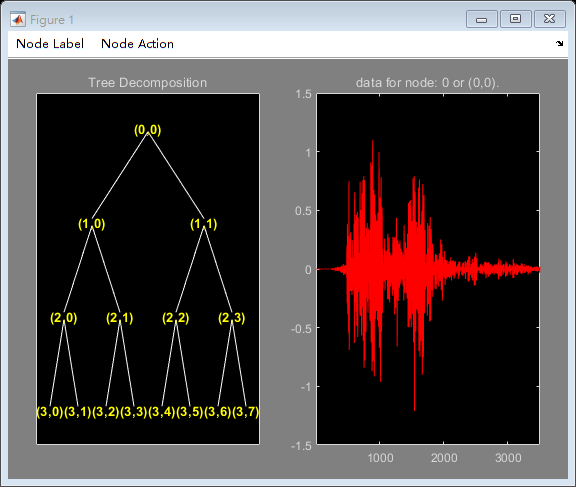

% case 1
RCF6_x = data(dur,3);
RCF6_y = data(dur,2);
relacc1 = RCF6_x - RCF6_y;
x1 = lowpass(relacc1,50,sr);
y1 = downsample(x1,4);
wpt1 = wpdec(y1,3,'db1');
plot(wpt1)

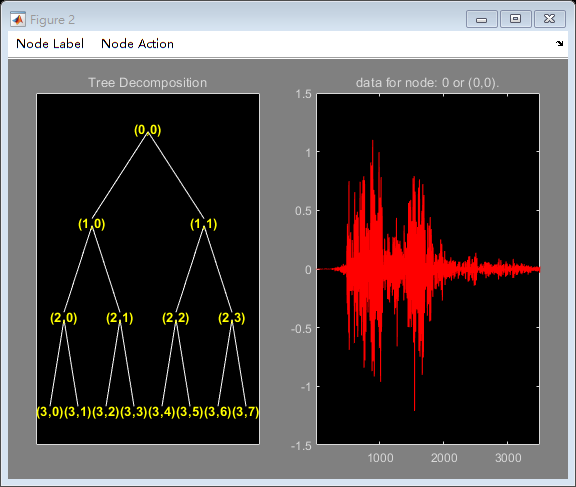


% case 2
RCF4_x = data(dur,7);
RCF4_y = data(dur,6);
relacc2 = RCF4_x - RCF4_y;
x2 = lowpass(relacc1,50,sr);
y2 = downsample(x1,4);
wpt2 = wpdec(y2,3,'db1');
plot(wpt2)

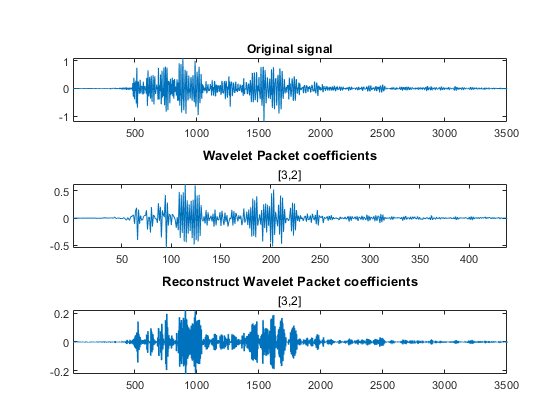

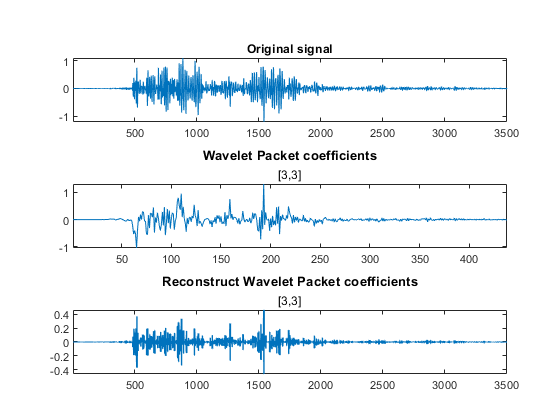

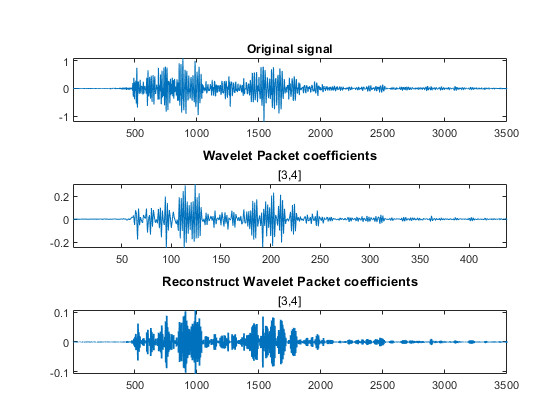

str = [y1 y2];
wpt = [wpt1 wpt2];
casename = ['case1'; 'case2'];
titlename = ['[3,2]';'[3,3]';'[3,4]'];
for i = 1:2
    cfs32 = wpcoef(wpt(:,i),[3,2]);
    rcfs32 = wprcoef(wpt(:,i),[3,2]);
    cfs33 = wpcoef(wpt(:,i),[3,3]);
    rcfs33 = wprcoef(wpt(:,i),[3,3]);
    cfs34 = wpcoef(wpt(:,i),[3,4]);
    rcfs34 = wprcoef(wpt(:,i),[3,4]);
    cfs = [cfs32 cfs33 cfs34];
    rcfs = [rcfs32 rcfs33 rcfs34];

    for j = 1:3
        figure
        subplot(3,1,1)
        plot(str(:,i))
        title('Original signal')
        axis tight

        subplot(3,1,2)
        plot(cfs(:,j))
        [t,s] = title('Wavelet Packet coefficients', convertCharsToStrings(titlename(j,:)));
        t.FontSize = 10;
        axis tight

        subplot(3,1,3)
        plot(rcfs(:,j))
        [t,s] = title('Reconstruct Wavelet Packet coefficients', convertCharsToStrings(titlename(j,:)));
        t.FontSize = 10;
        axis tight
        % saveas(gcf,fullfile(cd,'Packet (3,2).png'))
        % saveas(gcf,fullfile(cd,'Packet (3,2).fig'))
    end
end

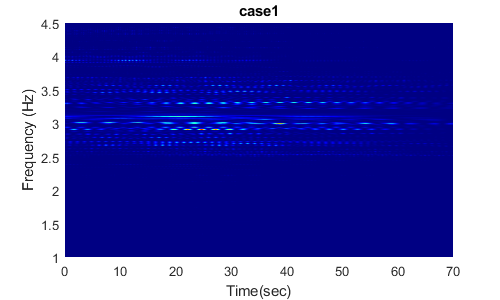

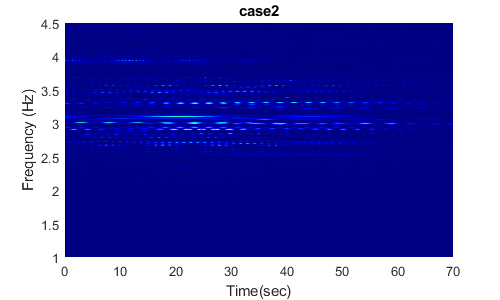

for i = 1:2
    [t,F,E,A,T,C] = wptspect(str(:,i),50,11);
    temp = find(F<=50);
    figure('Position',[200 50 500 300])
    surf(t,F(temp),E(:,temp)','LineStyle','none','FaceColor','interp','FaceLighting','phong','EdgeColor','interp')
    view(0,90),colormap('jet')
    ylim([1 4.5])
    xlabel('Time(sec)')
    ylabel('Frequency (Hz)')
    xlim([0 t(end)])
    title(casename(i,:))
end

function[t,F,E,A,T,C] = wptspect(u,SR,level)
if size(u,1) == 1
    u = u';
end
wname = 'bior6.8';
dt = 1/SR;
N = max(size(u));
t = [0:dt:(N-1)*dt];
% index of paley order
index = 0;
for i = 1:1:level
    index = [index fliplr(index)+2^(i-1)];
end
index = index + 1;

T = wpdec(u,level,wname);

A=zeros(length(u),2^level);
for i = 1:2^level
    C(:,i) = wprcoef(T,[level,index(i)-1]);

    A(:,i) = abs(hilbert(wprcoef(T,[level,index(i)-1])));
end
E = A.*A;
F = linspace(0,1/dt/2,2^level);
end

